Definicja ukladu ciągłego:

% state-space
A = [-1, 5 1; 0, -2, 1; 0, 0, -1];
B = [0; 0; 1];
C = [1, 0, 0];
sys = ss(A, B, C, 0)


sys =
 
  A = 
       x1  x2  x3
   x1  -1   5   1
   x2   0  -2   1
   x3   0   0  -1
 
  B = 
       u1
   x1   0
   x2   0
   x3   1
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


% transmitancja
[num, den] = ss2tf(A, B, C, 0);
G = tf(num, den)


G =
 
          s + 7
  ---------------------
  s^3 + 4 s^2 + 5 s + 2
 
Continuous-time transfer function.
Model Properties


Dyskretyzacja modelu w przestrzeni stanów i transmitancji:

T = 1.94;

% state-space
sys_d = c2d(sys, T, 'tustin')


sys_d =
 
  A = 
            x1       x2       x3
   x1  0.01523    1.675    1.325
   x2        0  -0.3197    0.335
   x3        0        0  0.01523
 
  B = 
           u1
   x1   1.285
   x2  0.3249
   x3  0.9848
 
  C = 
           x1      x2      x3
   y1  0.5076  0.8374  0.6623
 
  D = 
           u1
   y1  0.6424
 
Sample time: 1.94 seconds
Discrete-time state-space model.


% transmitancja
G_d = c2d(G, T, 'tustin')


G_d =
 
  0.6424 z^3 + 1.762 z^2 + 1.597 z + 0.4775
  -----------------------------------------
  z^3 + 0.2893 z^2 - 0.009506 z + 7.415e-05
 
Sample time: 1.94 seconds
Discrete-time transfer function.
Model Properties


G_d_zoh = c2d(G, T, 'zoh');
G_d_foh = c2d(G, T, 'foh');
G_d_impulse = c2d(G, T, 'impulse');
G_d_matched = c2d(G, T, 'matched');
G_d_least_squares = c2d(G, T, 'least-squares');

Sprawdzenie stabilności wersji dyskretnej:

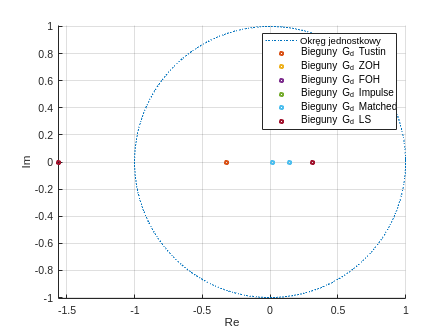

den = G_d.Denominator{1};
poles = roots(den);

den_zoh = G_d_zoh.Denominator{1};
poles_zoh = roots(den_zoh);
den_foh = G_d_foh.Denominator{1};
poles_foh = roots(den_foh);
den_impulse = G_d_impulse.Denominator{1};
poles_impulse = roots(den_impulse);
den_matched = G_d_matched.Denominator{1};
poles_matched = roots(den_matched);
den_least_squares = G_d_least_squares.Denominator{1};
poles_least_squares = roots(den_least_squares);

figure();
grid on;
hold on;
xlabel("Re");
ylabel("Im");
axis equal;
legend("show");

theta = 0:0.01:2*pi;
plot(cos(theta), sin(theta), ":", "DisplayName", "Okręg jednostkowy");
plot(real(poles), imag(poles), "o", "LineWidth", 2, "MarkerSize", 3, "DisplayName", "Bieguny G_d Tustin");
plot(real(poles_zoh), imag(poles_zoh), "o", "LineWidth", 2, "MarkerSize", 3, "DisplayName", "Bieguny G_d ZOH");
plot(real(poles_foh), imag(poles_foh), "o", "LineWidth", 2, "MarkerSize", 3, "DisplayName", "Bieguny G_d FOH");
plot(real(poles_impulse), imag(poles_impulse), "o", "LineWidth", 2, "MarkerSize", 3, "DisplayName", "Bieguny G_d Impulse");
plot(real(poles_matched), imag(poles_matched), "o", "LineWidth", 2, "MarkerSize", 3, "DisplayName", "Bieguny G_d Matched");
plot(real(poles_least_squares), imag(poles_least_squares), "o", "LineWidth", 2, "MarkerSize", 3, "DisplayName", "Bieguny G_d LS");

Wyznaczenie macierzy układu zamkniętego z regulatorem proporcjonalnym $u=\mathrm{Kx}$

syms K real positive 
syms lambda 

Adz = simplify(sys_d.A - sys_d.B * K * sys_d.C);
cp = charpoly(Adz, lambda);

cp_col = collect(cp, lambda);
[coeffs_cp, powers] = coeffs(cp_col, lambda);

a3 = coeffs_cp(powers == lambda^3);
a2 = coeffs_cp(powers == lambda^2);
a1 = coeffs_cp(powers == lambda);
a0 = coeffs_cp(powers == 1);

S1 = [ ...
    a3, a2, a1; ...
     0, a3, a2; ...
     0,  0, a3 ...
];
S2 = [ ...
    a0, a1, a2; ...
     0, a0, a1; ...
     0,  0, a0; ...
];
P = S1'*S1 - S2'*S2;

p_delta = simplify([det(P(1,1)); det(P(1:2,1:2)); det(P(1:3,1:3)); det(P)]);
stable_k = solve(p_delta > 0, K, ReturnConditions=true)

stable_k = struct with fields:
             K: x
    parameters: x
    conditions: x < 732919099237326886033549637944422170624/524885796186860929704655959849353287695 - (218424581927469056*148456831718881648708383173076292282072081^(1/2))/524885796186860929704655959849353287695 & 0 < x


cond_1 = simplify(stable_k.conditions(1));

ineq_1 = children(cond_1);

upper_1 = rhs(vpa(ineq_1(1), 10));
lower_1 = lhs(vpa(ineq_1(2), 10));

fprintf("x ∈ (%.4f, %.4f)\n", lower_1, upper_1);

x ∈ (0.0000, 1.2360)


Wartości własne ukłdau zamkniętego dla zakresu stabilnych $K$:

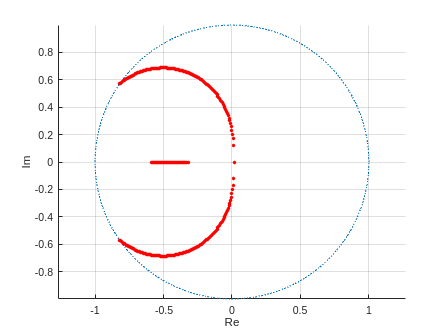

figure();
grid on;
hold on;
xlabel("Re");
ylabel("Im");
axis equal;

theta = 0:0.01:2*pi;
plot(cos(theta), sin(theta), ":", "DisplayName", "Okręg jednostkowy");

for k = lower_1:0.01:upper_1
    poles = eig(sys_d.A - sys_d.B * k * sys_d.C);
    plot(real(poles), imag(poles), "r.", "LineWidth", 4, "MarkerSize", 10);
end